%rpiを削除
clear rpi

%rpi接続設定
%家用
%rpi = raspi('192.168.0.53', 'pi', 'milkyway');
%大学用
rpi = raspi('10.24.84.39', 'pi', 'milkyway'); 

%
mycam = cameraboard(rpi,'Resolution','1280x720');

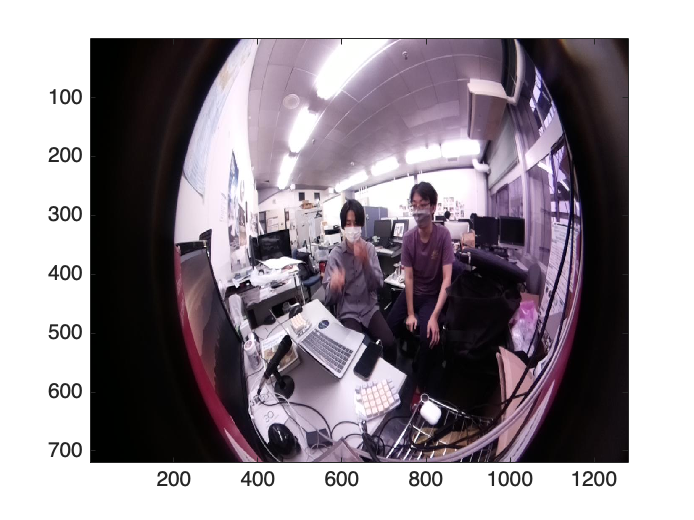

for ii = 1:100
img = snapshot(mycam);
    imagesc(img);
    mycam.Rotation = 180;
    drawnow
end

record(mycam,'myvideo.h264',60)

getFile(rpi,'myvideo.h264','/Users/daiki_daiku/Documents/MATLAB')
deleteFile(rpi,'myvideo.h264')

v=VideoReader('myvideo.h264')

次を使用中: VideoReader/initReader
必要なコーデックを特定できません。

エラー: audiovideo.internal.IVideoReader (行 136)
            initReader(obj, fileName, currentTime);

エラー: VideoReader (行 104)
          

次を使用中: mmfileinfo
必要なコーデックを特定できません。

%Lチカforループ(1秒間隔で点滅)
%>|matlab|
for i = 1:10
    writeLED(rpi, led, 0);
    pause(1);
    writeLED(rpi, led, 1);
    pause(1);
end
%LEDの制御を解放
system(rpi, 'echo "mmc0" | sudo tee /sys/class/leds/led0/trigger');
%rpiを削除
clear rpi